clear

data = readtable("calib_data_trzy_obroty.csv", "VariableNamingRule","preserve")

data = 238×11 table
    Var1       time         accX        accY        accZ       gyroX       gyroY        gyroZ       magX       magY      magZ  
    ____    __________    ________    _________    _______    ________    ________    _________    _______    ______    _______

      0     5.3632e+05    0.025191    -0.023869    0.99758     0.05368    0.093513     -0.31717     1.3034    11.697    -45.958
      1     5.3635e+05    0.025191    -0.023869    0.99758     0.05368    0.093513     -0.31717     1.1252    10.414    -44.861
      2      5.364e+05    0.028191    -0.026869     1.0076     0.15868    0.071513     -0.431

collected = readtable("collected_data_trzy_obroty.csv", "VariableNamingRule","preserve")

collected = 238×14 table
    Var1       time        accX       accY       accZ        gyroX        gyroY        gyroZ       magX      magY      magZ       roll         pitch         yaw   
    ____    __________    _______    _______    _______    _________    _________    _________    ______    ______    ______    _________    _________    _________

      0     5.3632e+05    0.24712    0.24712    0.27655    0.0009369    0.0009369    0.0027695    1.3034    1.1252    1.1252    -0.015039     0.007336    -0.013413
      

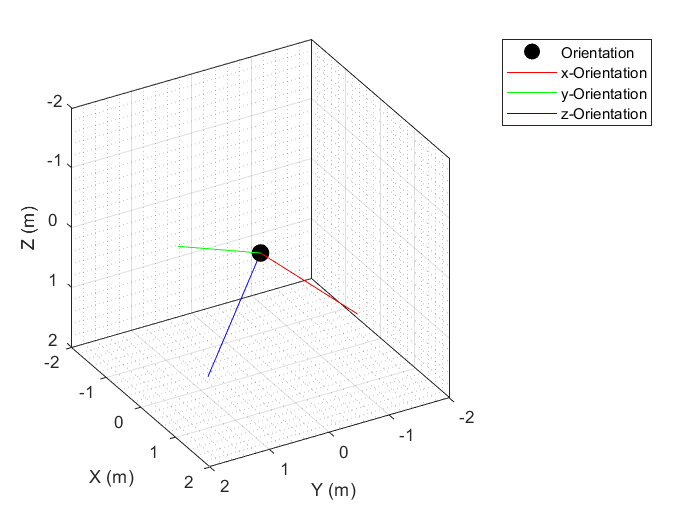

Index exceeds the number of array elements (238).

Error in tabular/dotParenReference (line 114)
        b = b(rowIndices);

figure()

tp = theaterPlot('XLimit',[-2 2],'YLimit',[-2 2],'ZLimit',[-2 2]);
op = orientationPlotter(tp,'DisplayName','Orientation',...
    'LocalAxesLength',2);

for i=1:numel(collected)
    plotOrientation(op, collected.roll(i), collected.pitch(i), collected.yaw(i))
    drawnow
end

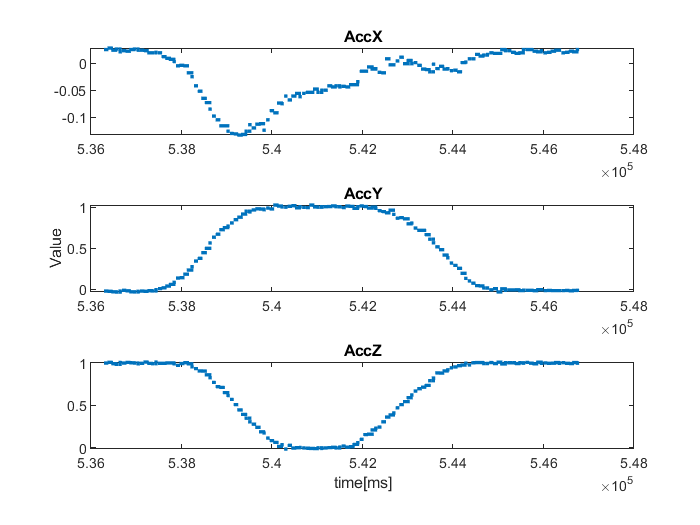

figure(1)
subplot(3,1,1)
plot(data.("time"), data.accX, '.')
title("AccX")

subplot(3,1,2)
plot(data.("time"), data.accY, '.')
title('AccY')
ylabel('Value')

subplot(3,1,3)
plot(data.("time"), data.accZ, '.')
title("AccZ")
xlabel('time[ms]')

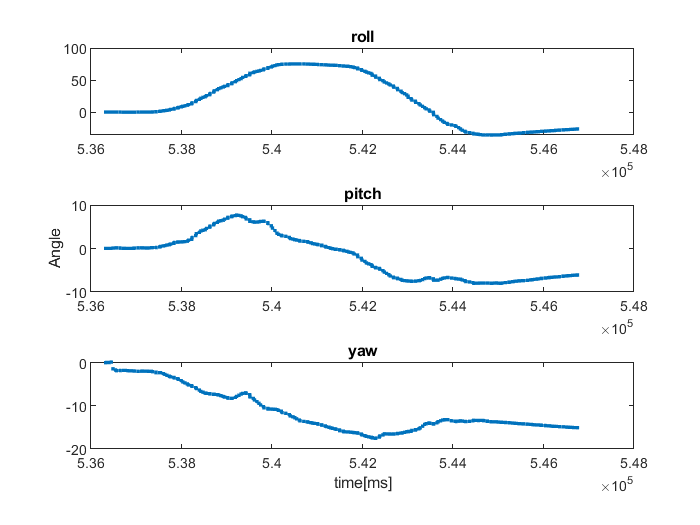

figure(2)
subplot(3,1,1)
plot(data.("time"), collected.roll, '.')
title("roll")

subplot(3,1,2)
plot(data.("time"), collected.pitch, '.')
title('pitch')
ylabel('Angle')

subplot(3,1,3)
plot(data.("time"), collected.yaw, '.')
title("yaw")
xlabel('time[ms]')